# What is "Programming" in Dynamical Neural Computation?

This tutorial establishes the fundamental paradigm shift from traditional machine learning to **Dynamic Neural Programming** (DNP):

- **Traditional ML**: "Here's data, learn the mapping"

- **DNP**: "Here are equations, compile them into weights"

By the end of this tutorial, you will understand:

- Why this is **compilation**, not **training**

- What the Program Matrix $P$ represents

- How the DNP formula $P = y + \frac{1}{\gamma}f(y)$ encodes dynamics

- Why no data or sampling is required

**Reference**: Kim & Bassett (2023) "A neural machine code and programming framework for the reservoir computer" *Nature Machine Intelligence*

[https://doi.org/10.1038/s42256-023-00668-8](https://doi.org/10.1038/s42256-023-00668-8)

## The Paradigm Shift

If you've worked with neural networks, you probably equate "programming" with "training." The usual recipe:

- Collect input-output data pairs $(x, y)$

- Define a loss function $L(W)$

- Run gradient descent to minimize $L$

- Hope the network generalizes

**This is NOT what we do here.**

Imagine you want a network to simulate exponential decay: $\dot{y} = -\alpha y$

**Traditional approach:** Simulate many trajectories, collect as training data, train a network to predict the next state.

**Our approach:** Write down the equation symbolically, DERIVE the weights. No simulation, no sampling, no training loop.

The weights come from **algebra**, not **optimization**.

This is **compilation**: source code (equations) $\rightarrow$ executable (weights)

## Setup: 

Run this to clear your workspace if you want

clearvars; clc; close all

## A Minimal Example: Exponential Decay

The simplest dynamical system:


$$\dot{y} = -\alpha y$$


with solution $y(t) = y_0 e^{-\alpha t}$

We will:

- Create a reservoir with 1 feedback variable

- Write the program matrix $P$ for this system

- Compile $P$ into weights $W$

- Simulate and verify against the analytic solution

% Decay rate
alpha = 2.0;

% Create reservoir
res = dspm_reservoir( ...
    'n_neurons', 50, ...           % 50 neurons (plenty for 1D linear)
    'n_recurrent_inputs', 1, ...   % 1 feedback variable (y)
    'n_external_inputs', 0, ...    % no external forcing
    'gamma', 100, ...              % network timescale
    'dt', 0.01, ...                % integration step
    'B_scale', 0.2, ...            % input weight scale
    'B_sparsity', 0.7, ...         % input sparsity
    'jet_order', 1, ...            % positions only (no velocities)
    'decompilation_order', 2, ...  % linear terms sufficient for this

Reservoir created:


    'verbose', false);

  Neurons: 50


  Feedback dim: 1


fprintf('Reservoir created:\n');

  Basis size: 2 monomials


fprintf('  Neurons: %d\n', res.n_neurons);

  gamma: 100, dt: 0.010



fprintf('  Feedback dim: %d\n', res.n_recurrent_inputs);
fprintf('  Basis size: %d monomials\n', res.n_monomials);
fprintf('  gamma: %.0f, dt: %.3f\n\n', res.gamma, res.dt);

## The DNP Formula

The heart of Dynamic Neural Programming:


$$P_{i,:} = y_i + \frac{1}{\gamma} f_i(y)$$


where:

- $P$ is the "program matrix" (what we want the network to compute)

- $y_i$ is the $i$-th state variable (identity term)

- $f_i(y)$ is the RHS of $\dot{y}_i = f_i(y)$

- $\gamma$ is the network time constant

For exponential decay $\dot{y} = -\alpha y$:


$$P = y + \frac{1}{\gamma}(-\alpha y) = \left(1 - \frac{\alpha}{\gamma}\right) y$$


With $\alpha = 2$ and $\gamma = 100$:


$$P = 0.98 \cdot y$$


That's the entire program: a single coefficient!

coeff = 1 - alpha / res.gamma;
fprintf('DNP formula for exponential decay:\n');
fprintf('  P = y + (1/gamma)*f(y)\n');
fprintf('    = y + (1/gamma)*(-alpha*y)\n');
fprintf('    = (1 - alpha/gamma)*y\n');
fprintf('    = (1 - %.1f/%.0f)*y\n', alpha, res.gamma);
fprintf('    = %.4f * y\n\n', coeff);

## Inspecting the Basis

The reservoir provides a polynomial basis. Let's see what terms are available for programming:

res.printBasis();

For our 1D system with `decompilation_order=2`, we have:

- Column 1: constant term (1)

- Column 2: linear term ($y$)

- Column 3: quadratic term ($y^2$)

We only need the $y$ column for linear dynamics.

idx_y = res.getColumnIndex('x1');  % Variables use x1, x2, ... naming
fprintf('\nColumn index for "y": %d\n\n', idx_y);

## Building the Program Matrix by Hand

The program matrix $P$ has shape `(n_outputs × n_monomials)`.

For 1D with coefficient 0.98 on the $y$ term:

P = zeros(1, res.n_monomials);
P(1, idx_y) = coeff;

fprintf('Program matrix P (built by hand):\n');
disp(array2table(P, 'VariableNames', res.symbolic_basis_strings));

## Compilation: $P \rightarrow W$

Compilation finds output weights $W$ such that $W \cdot R \approx P$.

The $R$ matrix (decompiled representation) shows how each neuron responds to each monomial. Compilation solves:


$$W = \arg\min_W \|W R - P\|_F$$


This is **least squares**, not gradient descent on data!

R = res.decompiled_weight_matrix;
fprintf('R matrix: %d neurons x %d monomials\n\n', size(R,1), size(R,2));

R matrix: 50 neurons x 2 monomials




[residual, rank_R, stats] = res.compile(P);

fprintf('Compilation results:\n');

Compilation results:


fprintf('  Residual: %.2e\n', residual);

  Residual: 2.73e-16


fprintf('  Relative error: %.4f%%\n', stats.rel_error * 100);

  Relative error: 0.0000%


fprintf('  Rank(R): %d/%d\n\n', rank_R, res.n_monomials);

  Rank(R): 2/2



## Simulation

Now we close the loop, condition to an initial state, and simulate.

% Close feedback loop: A = B*W
A_tilde = res.close_loop();
fprintf('Loop closed. ||A||_F = %.4f\n', norm(A_tilde, 'fro'));

Loop closed. ||A||_F = 1.0686



% Initial condition
y0 = 1.0;
res.condition(y0);
fprintf('Conditioned to y0 = %.2f\n\n', y0);

Conditioned to y0 = 1.00




% Simulate
T_steps = 500;
[~, y_sim] = res.simulate(T_steps);

% Time vector and analytic solution
t = (0:T_steps-1) * res.dt;
y_true = y0 * exp(-alpha * t);

% Error
mse = mean((y_sim - y_true).^2);
fprintf('MSE vs analytic solution: %.2e\n', mse);

MSE vs analytic solution: 2.41e-03


## Visualization, Programming = Compilation, Not Training

Trajectory comparison

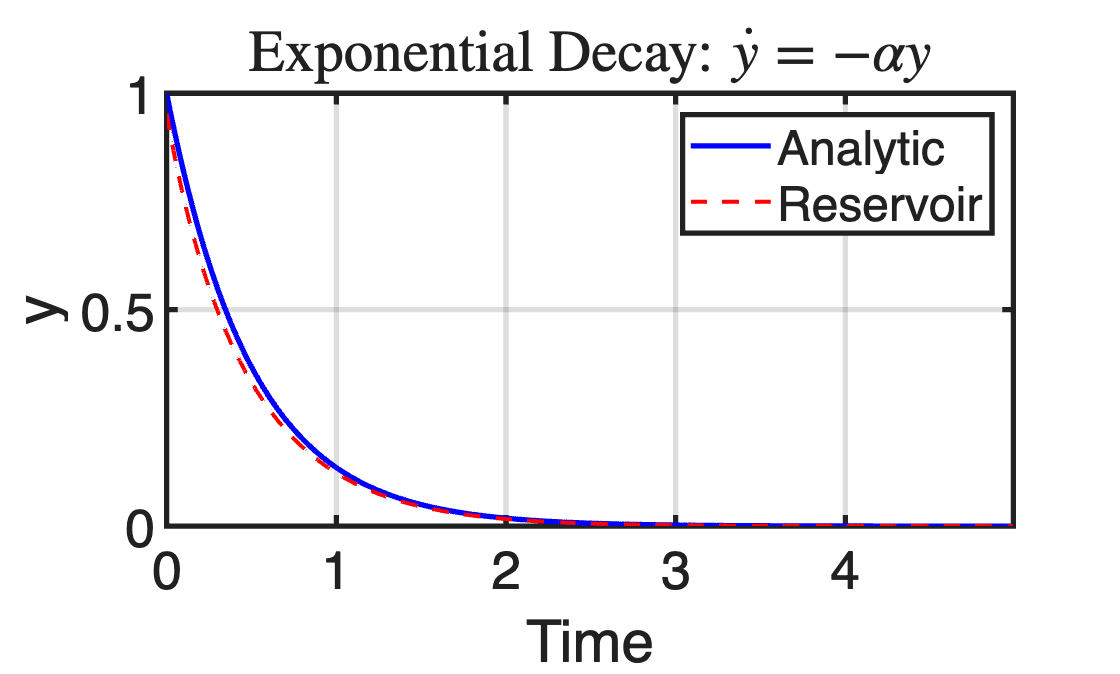

plot(t, y_true, 'b-', 'LineWidth', 2, 'DisplayName', 'Analytic');
hold on;
plot(t, y_sim, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Reservoir');
hold off;
xlabel('Time'); ylabel('y');
title('Exponential Decay: $\dot{y} = -\alpha y$', 'Interpreter', 'latex');
legend('Location', 'northeast');
grid on; xlim([0, t(end)]);

 Error

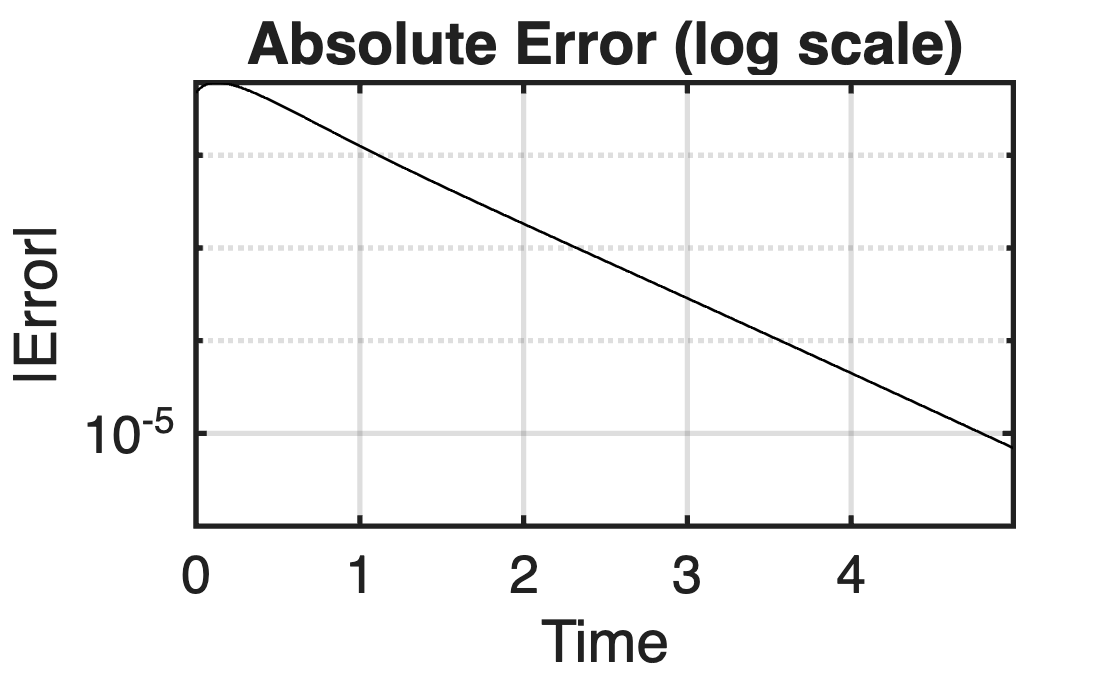

semilogy(t, abs(y_sim - y_true) + 1e-16, 'k-', 'LineWidth', 1);
xlabel('Time'); ylabel('|Error|');
title('Absolute Error (log scale)');
grid on; xlim([0, t(end)]);

$P[\phi(y)]$ vs $W*R[\phi(y)]$

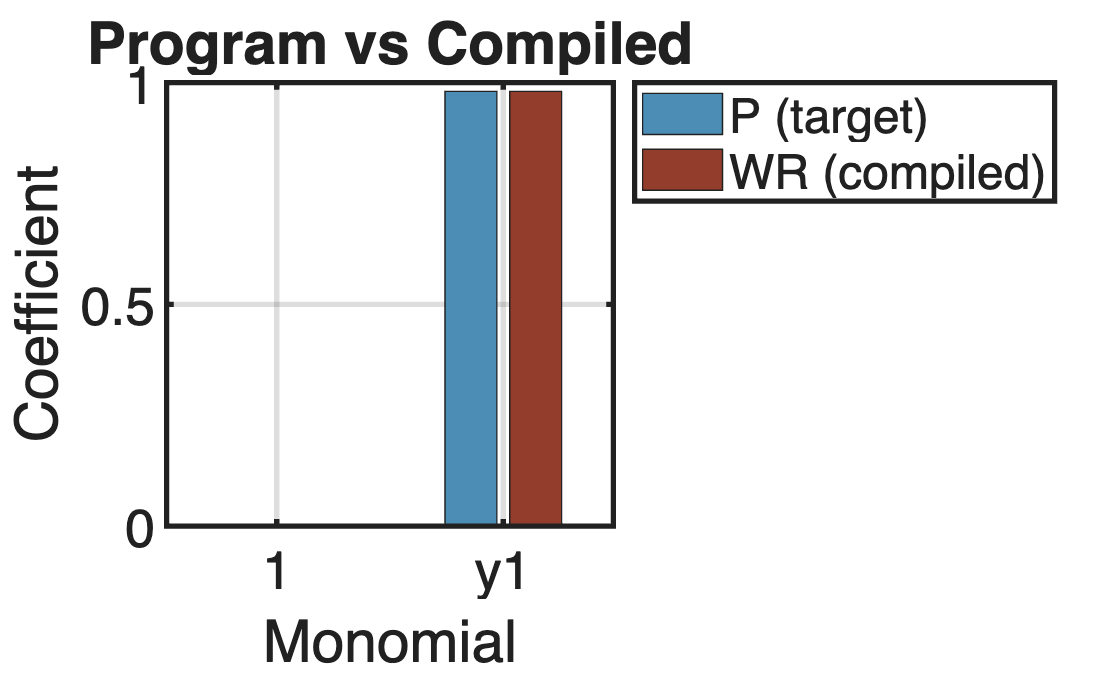

WR = res.read_out_matrix_recurrent * R;
bar(1:res.n_monomials, [P; WR]');
xlabel('Monomial'); ylabel('Coefficient');
title('Program vs Compiled');
legend({'P (target)', 'WR (compiled)'}, 'Location', 'bestoutside');
xticks(1:res.n_monomials);
xticklabels(res.symbolic_basis_strings);
grid on;

## The Preferred Method: Symbolic Interface

Building $P$ by hand is instructive but error-prone. The preferred method uses symbolic expressions:

This automatically:

- Extracts coefficients from the symbolic expression (using `[weights,variables]=coeffs(dy);)`

- Maps them to the correct basis columns

- Applies the DNP formula $P = y + \frac{1}{\gamma}f(y)$

- Compiles $P$ into $W$, via taking the least-squares min norm that effectively implements $W = P(R)^{-1}$

- Note that $R$ here refers to the derivative polynomial approximation weights from our symbolic dynamcis such that $R\phi(y) \approx \left(r + \frac{1}{\gamma}\dot{r}\right)$, where $\phi(y)$ is the set of all *monomial* terms that compose to make the polynomial expansion of our update equation's solution.

% Fresh reservoir with same parameters
res2 = dspm_reservoir( ...
    'n_neurons', 50, ...
    'n_recurrent_inputs', 1, ...
    'n_external_inputs', 0, ...
    'gamma', 100, 'dt', 0.01, ...
    'B_scale', 0.2, 'B_sparsity', 0.7, ...
    'jet_order', 1, 'decompilation_order', 2, ...
    'verbose', false);

% Symbolic programming (one line!)
syms x1 real
dy = -alpha * x1;
res2.program(dy);

% Compare P matrices
fprintf('\nP matrix comparison:\n');


P matrix comparison:


fprintf('  By hand:  %.6f (at y column)\n', P(1, idx_y));

  By hand:  0.980000 (at y column)


fprintf('  Symbolic: %.6f (at y column)\n', res2.compiled_program_matrix(1, idx_y));

  Symbolic: 0.980000 (at y column)


fprintf('  Match: %s\n', string(norm(P - res2.compiled_program_matrix) < 1e-10));

  Match: true


## Key Takeaways

**The Paradigm Shift:**

**The DNP Formula:**


$$P = y + \frac{1}{\gamma} f(y)$$


This encodes:

- The state identity, $y(t)$, "where am I now?"

- The dynamics, $\frac{1}{\gamma} f(y,t)$, "where am I going?"

**The network doesn't "learn" dynamics. It IMPLEMENTS them.**

**The weights are DERIVED, not FITTED.**

## Experiments to Try

- **Change **$\alpha$: What happens as $\alpha \rightarrow \gamma$? (Hint: $P \rightarrow 0$)

- **Change **$\gamma$: How does network timescale affect accuracy?

- **Change** `n_neurons`: How few can you use for 1D linear dynamics?

- **Try **$\dot{y} = +\alpha y$: What happens with unstable dynamics?

## Next Tutorial

**s02_the_program_matrix.m** - Deeper dive into the DNP formula with multi-dimensional systems (harmonic oscillator).